## `Color Thresholding Evaluation with MATLAB`

### `Samuel Adkins`

### `Z23557914`

### `MATLAB Assignment 2, Feb 11th 2024`

`This script describes, evaluates, and demonstrates the process of using MATLAB's Color Thresholder tool to segment objects of a specific color from an image.`

`Inspiration from Steve Eddins who reviewed an older version of the tool with the L*a*b color space in his post:`

`https://blogs.mathworks.com/steve/2014/04/25/color-thresholder-app-in-r2014a/`

**Different functionality:**

The Color Thresholder app is designed for segmenting color images by applying thresholds within different color spaces. It supports four color spaces, allowing the user to dynamically work with multiple imaging scenarios. The app allows you to create binary segmentation masks, which are essential for isolating specific elements based on colors within the image.

**How it works:**

The app works by letting the user set threshold color channels for chosen color spaces. Then, the user can manipulate the thresholds by adjusting the color channel values directly or by interacting with the 3-D color space plot. The 3-D plot helps to accurately choose the best color ranges to include in the segmentation mask.

**Installation:**

This app comes built-in with MATLAB’s Image Processing Toolbox, so there is no extra installation required. 

However, the tool does not seem to work in the online version of MATLAB.

**Testing:**

To test the Color Thresholder, we can create a simple process in MATLAB to load a color image, choose a color space, and then adjust the thresholds to segment the image. Then we can evaluate the resulting mask by how well the mask isolates the desired objects or regions from the rest of the image.

For this, I will use the peppers.png image as the default choice, and attempt to create a color mask that only shows the red peppers.

### `Step 1: Display the Original Image`

% Load and display the original image.
originalImage = imread('peppers.png');
figure;
imshow(originalImage);
title('Original Image');

### `Step 2: Open the image with the Color Thresholder and create the mask.`

colorThresholder(originalImage)


Here, we can see the image in the Color Thresholder application and we are going to choose the RGB color space:

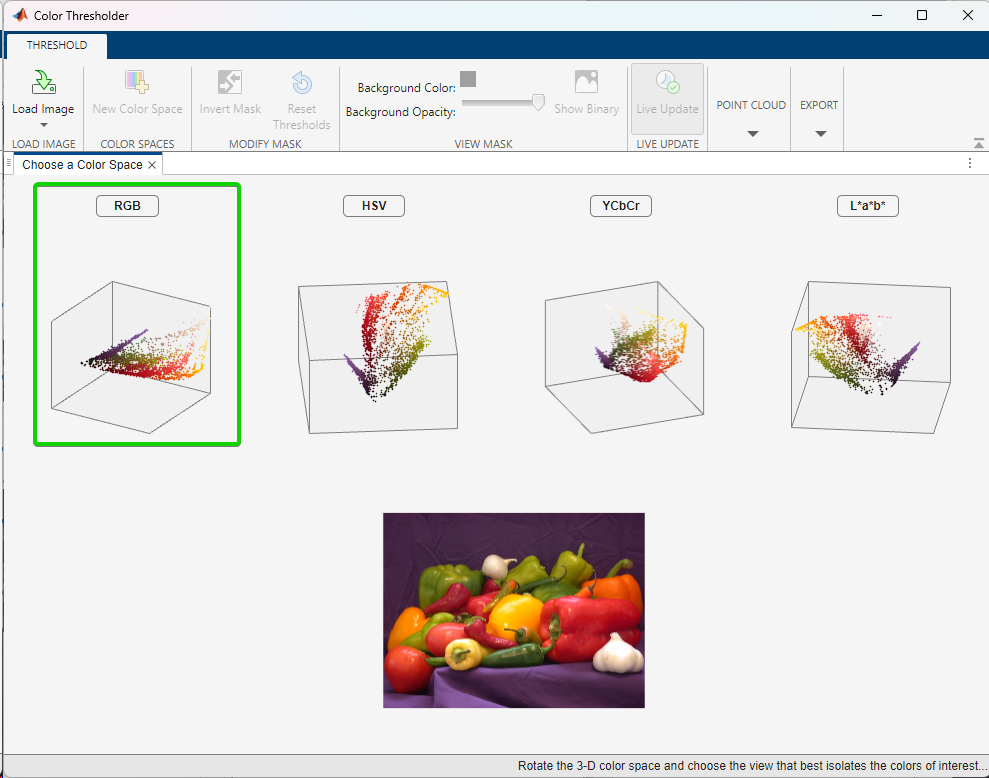

`Now we see the point cloud and can create by adjusting the sliders (small blue tabs) for the RGB threshold values. The result will be immediate in both the point cloud and displayed image:`

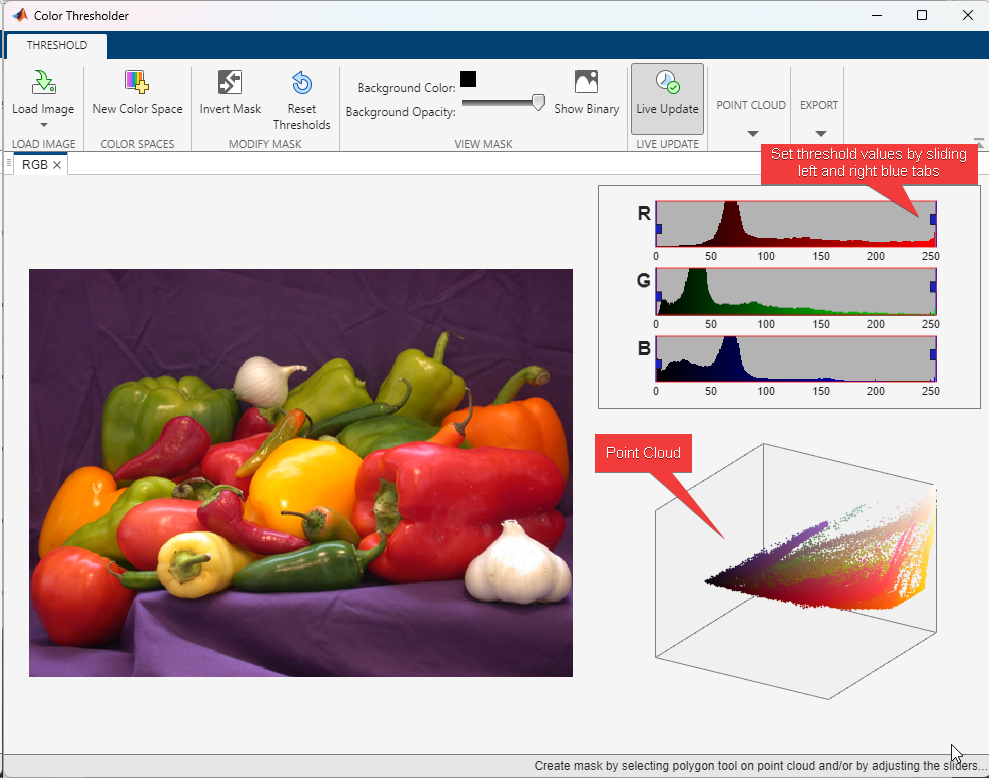

`First we can remove the dark blues in the green and yellow peppers by adjusting the left B slider and some whites in the onion and peppers with the right blue slider like so:`

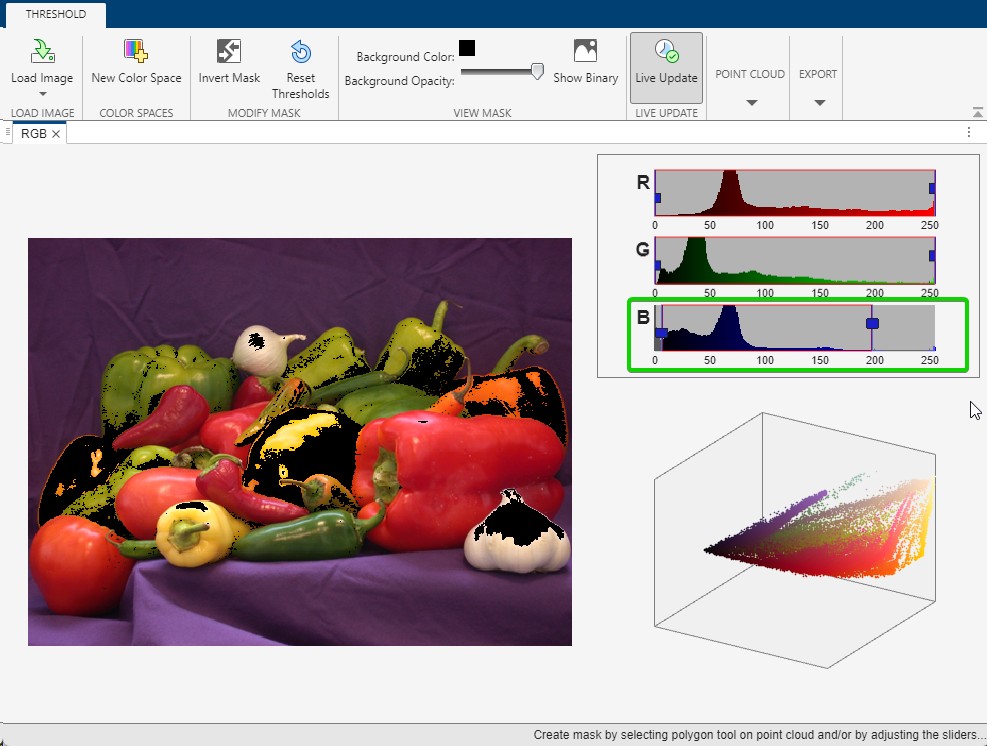

Next with the green slider, move the left 'G' tab immediatly removes red in the peppers but moving the right tab gets rid of most of the green in the green peppers. (experimentation is key):

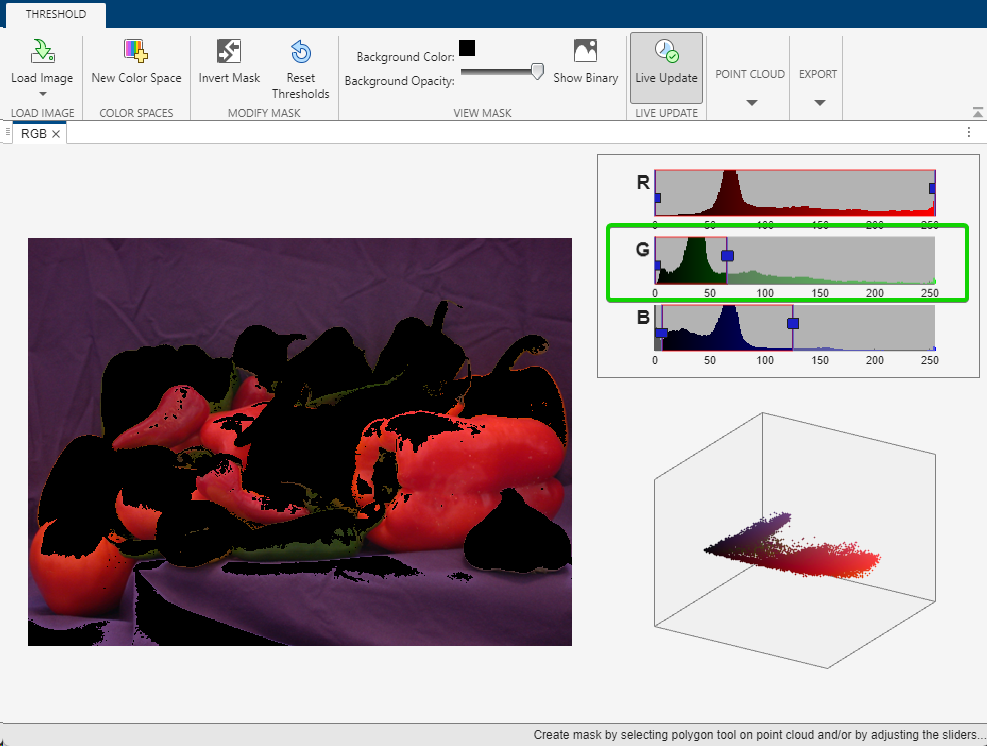

Then if we adjust the red sliders slightly, we can remove the dark reds that make t he rest of the leftover green:

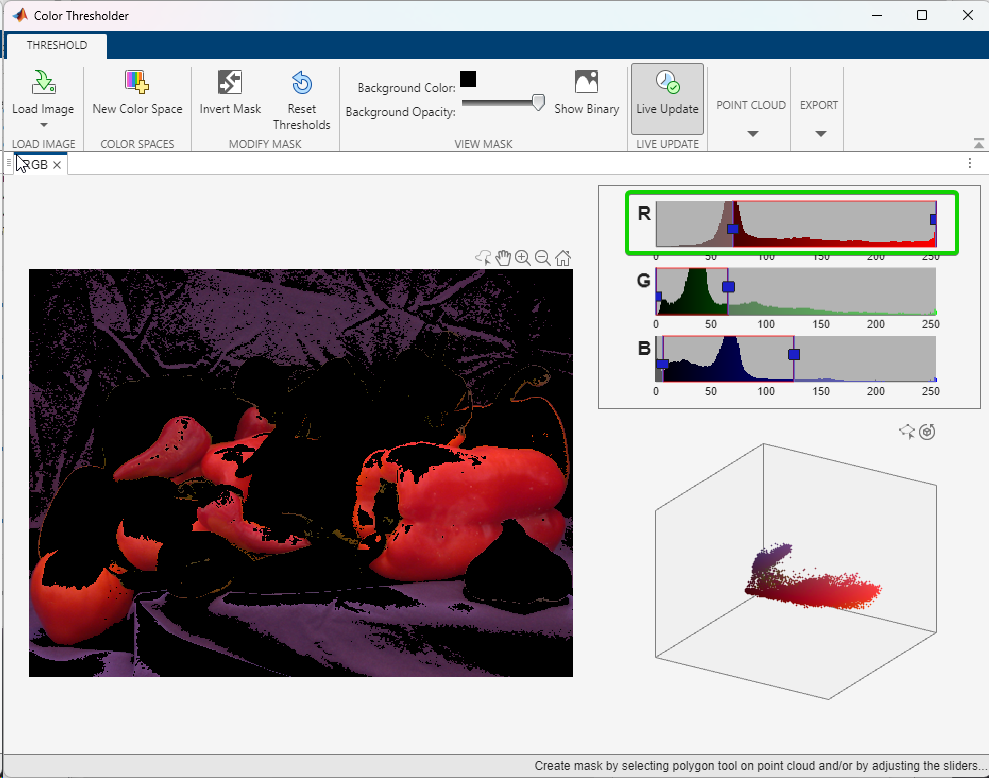

`Lastly we can export our custom mask after making last minute adjustments like can bringing in the blue slider a bit more to remove the purple cloth, as so:`

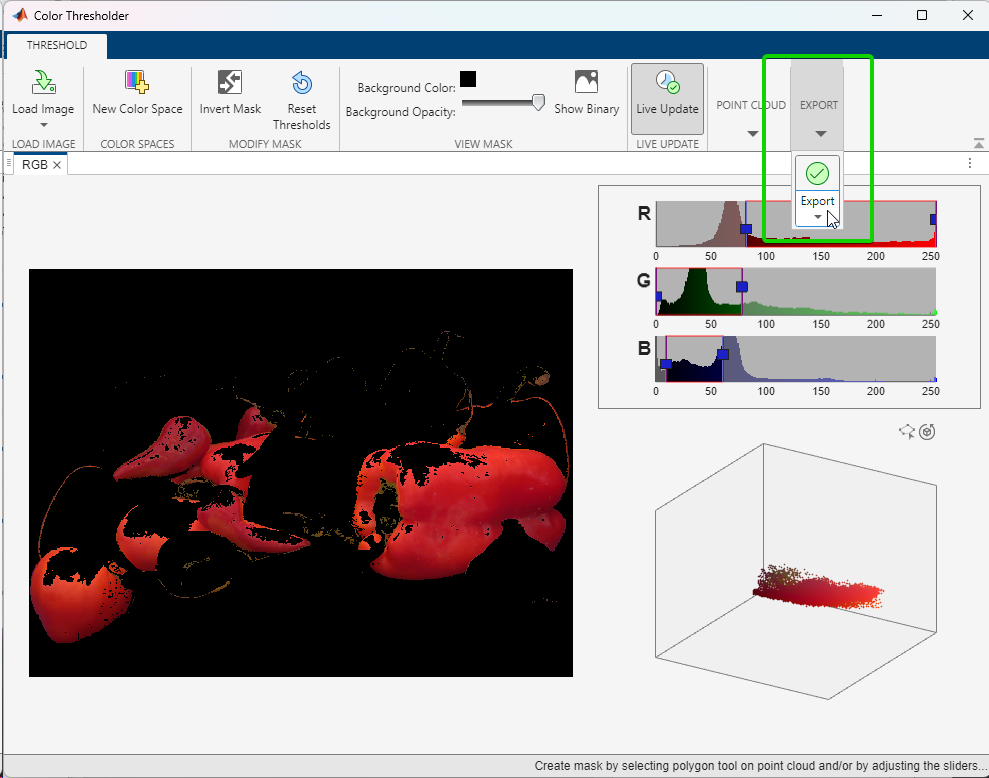

### Step 3: The Exported Code

After setting the custom color thresholding values and selecting export, the resulting code is (actual code at the bottom of this LiveScript):

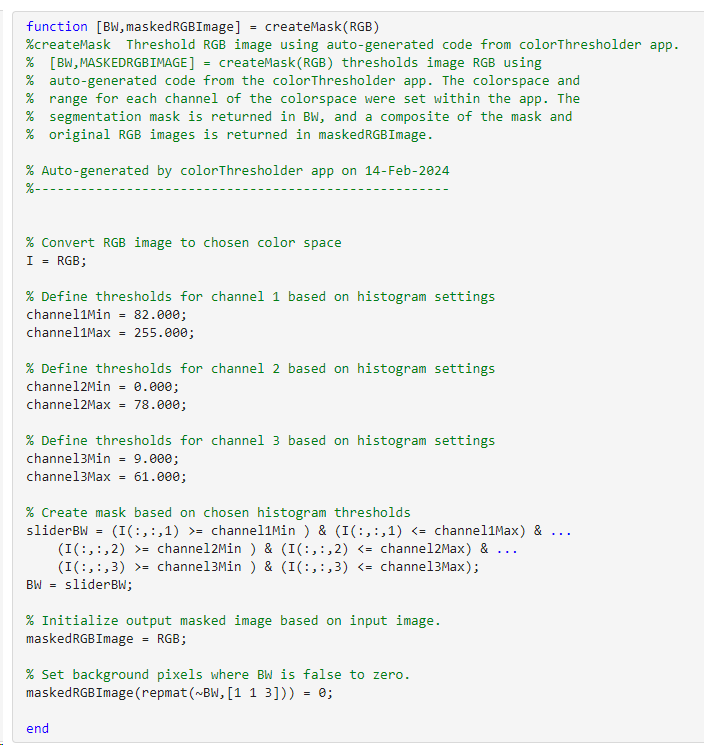

#### `Let's test that exported function to see our red pepper mask in action:`

[bWoutputImage, colorMaskedImage] = createMask(originalImage);
imshow(colorMaskedImage);
title('Segmented Image');

`The exported code also automatically creates the BW mask equivalent:`

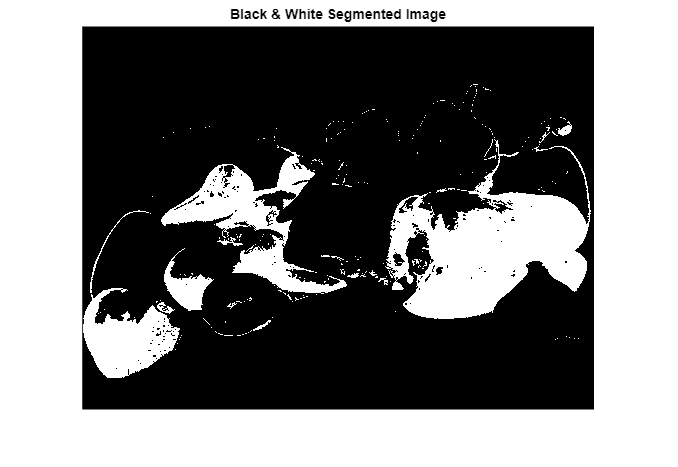

imshow(bWoutputImage);
title('Black & White Segmented Image');

`All together:`

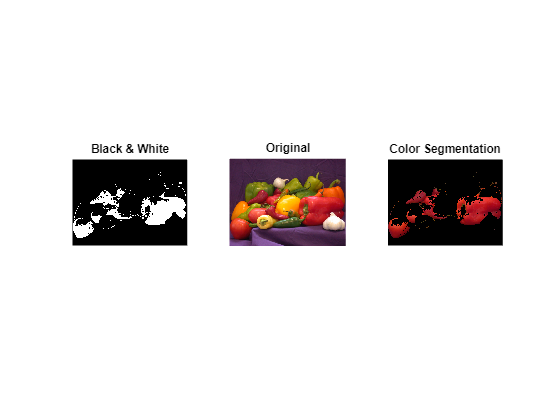

figure, subplot(1,3,1), imshow(bWoutputImage), title('Black & White');
subplot(1,3,2), imshow(originalImage), title('Original');
subplot(1,3,3), imshow(colorMaskedImage), title('Color Segmentation');

### `Analysis`

#### `Function required at buttom of LiveScript:`

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 14-Feb-2024
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 82.000;
channel1Max = 255.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 78.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 9.000;
channel3Max = 61.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end